# LAB6B: DC Motor Speed Controller

Open serial port.

clear s % closes ports already open
s = serialport('COM11',9600) % Check COM#

Read serial port values and parse data into lists. 

t = zeros(1, 90);
pos = zeros(1, 90);
spd = zeros(1, 90);
inpt = zeros(1, 90);
error = zeros(1, 90);

% loop through all 
for n = 1:90
    msg = s.readline();
    items = split(msg, ',');
    vals = arrayfun(@str2num, items);
    t(n) = vals(1);
    pos(n) = vals(2);
    spd(n) = vals(3);
    inpt(n) = vals(4);
    error(n) = vals(5);
end

%save lab6b_3.mat t pos spd inpt error

load lab6b_1.mat

Calculate steady state value, steady state gain, and time constant. 

Omega_ss = mean(spd(end-14:end)) % steady state speed

Omega_ss = 34.7191

SSG = Omega_ss / 3 % steady state gain Fv/M M=3 (3V input)

SSG = 11.5730


[SPD, ia, ic] = unique(spd); % grab only unique values of spd
tau = interp1(SPD, t(ia), 0.63 * Omega_ss) % calculate time at 0.63 * Omega_ss

tau = 0.0803

Calculate settling time 

i = find(spd >= 0.98 * Omega_ss);

T_s = t(i(1))

T_s = 0.1930

Calculate a & b of transfer function

a = 1/tau

a = 12.4596

b = SSG * a

b = 144.1950

Plot speed, angle, input voltage, and error with respect to time. 

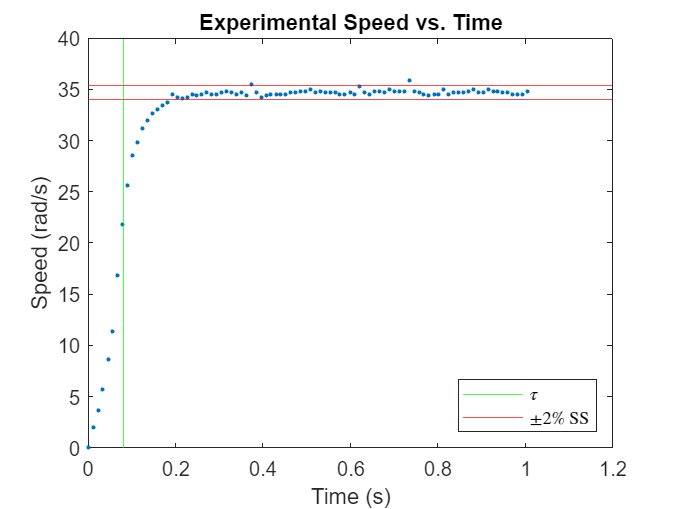

% plot speed
plot(t,spd, '.')
xline(tau, 'g')
yline(0.98 * Omega_ss, 'r')
yline(1.02 * Omega_ss, 'r')
title("Experimental Speed vs. Time")
xlabel("Time (s)")
ylabel("Speed (rad/s)")
legend({'', '$\tau$', '$\pm{2\%}$ SS'},'Interpreter','latex', 'Location','southeast') 

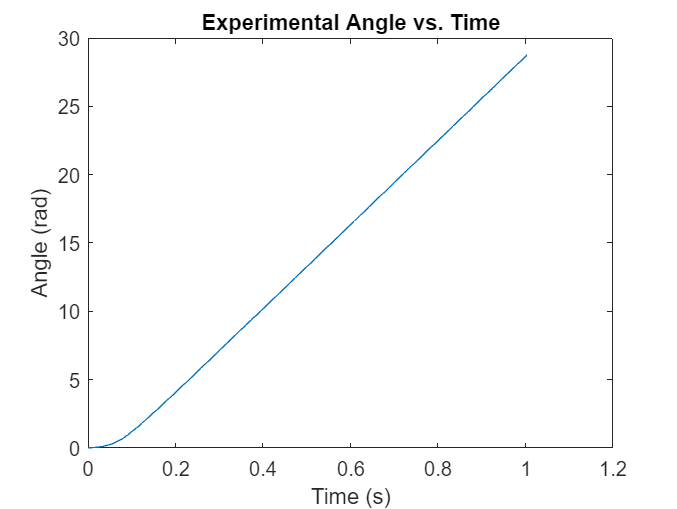


% plot angle
plot(t,pos)
title("Experimental Angle vs. Time")
xlabel("Time (s)")
ylabel("Angle (rad)")

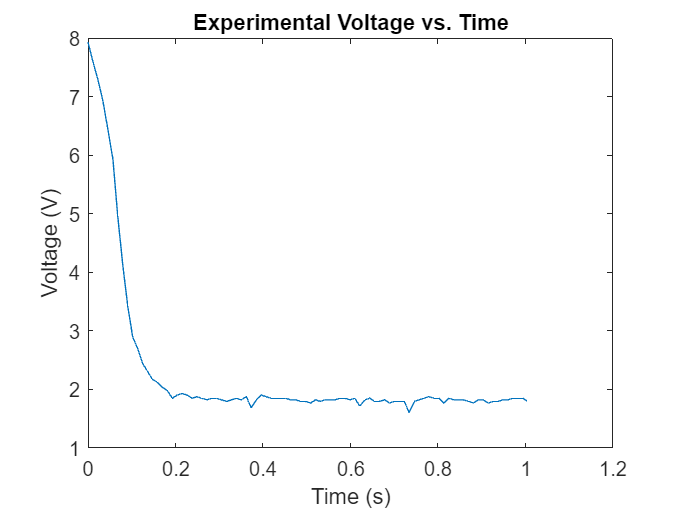


% plot input voltage
plot(t,inpt)
title("Experimental Voltage vs. Time")
xlabel("Time (s)")
ylabel("Voltage (V)")

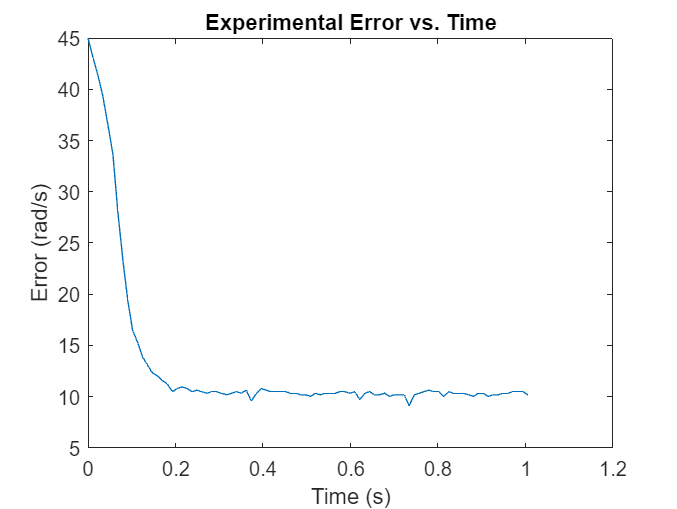


% plot error
plot(t, error)
title("Experimental Error vs. Time")
xlabel("Time (s)")
ylabel("Error (rad/s)")

% load data from all three trials
trial1 = load('lab6b_1.mat');
time1 = trial1.t;
speed1 = trial1.spd;
input1 = trial1.inpt;
error1 = trial1.error; 

trial2 = load('lab6b_2.mat');
time2 = trial2.t;
speed2 = trial2.spd;
input2 = trial2.inpt;
error2 = trial2.error; 

trial3 = load('lab6b_3.mat');
time3 = trial3.t;
speed3 = trial3.spd;
input3 = trial3.inpt;
error3 = trial3.error; 

% calculate mean values
time = (time1 + time2 + time3) / 3;
speed = (speed1 + speed2 + speed3) / 3;
input = (input1 + input2 + input3) / 3;
error = (error1 + error2 + error3) / 3;

% calculate omega_ss and tau
Omega_ss = mean(speed(end-14:end)) % steady state speed

Omega_ss = 34.6202

SSG = Omega_ss / 3 % steady state gain Fv/M M=3 (3V input)

SSG = 11.5401


[SPD, ia, ic] = unique(speed); % grab only unique values of spd
tau = interp1(SPD, time(ia), 0.63 * Omega_ss) % calculate time at 0.63 * Omega_ss

tau = 0.0800


% calculate settling time 
i = find(spd >= 0.98 * Omega_ss);

F_v_exp = mean(speed(end-10:end)) % calculate final value

F_v_exp = 34.6215


SSE_exp = 45 - F_v_exp

SSE_exp = 10.3785


T_s_exp = time(i(1))

T_s_exp = 0.1923

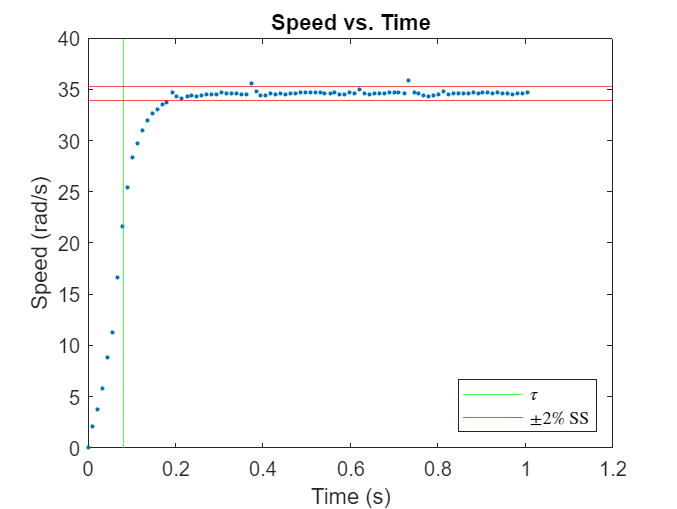

% plot speed
plot(time, speed, '.')
xline(tau, 'g')
yline(0.98 * Omega_ss, 'r')
yline(1.02 * Omega_ss, 'r')
title("Speed vs. Time")
xlabel("Time (s)")
ylabel("Speed (rad/s)")
legend({'', '$\tau$', '$\pm{2\%}$ SS'},'Interpreter','latex', 'Location','southeast') 

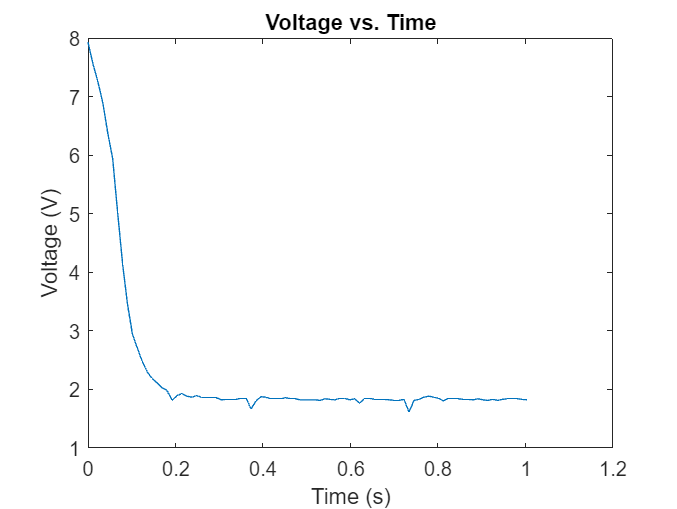


% plot input voltage
plot(time, input)
title("Voltage vs. Time")
xlabel("Time (s)")
ylabel("Voltage (V)")

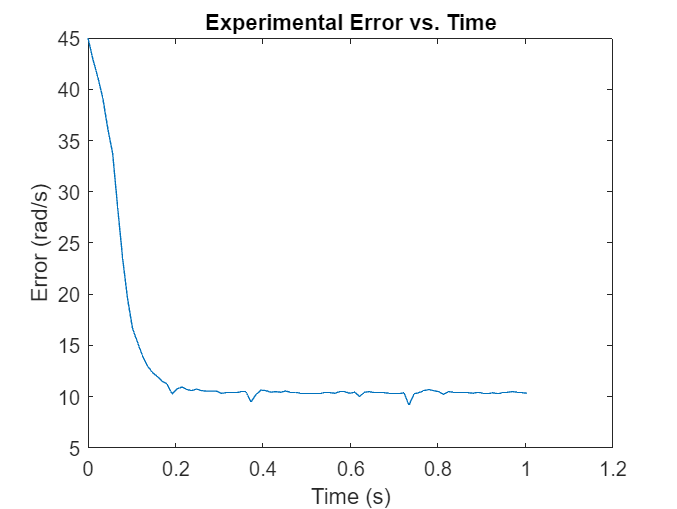


% plot error
plot(time, error)
title("Experimental Error vs. Time")
xlabel("Time (s)")
ylabel("Error (rad/s)")

% coefficients
a = 3.6029;
b = 70.3493;
K = 0.1762; % poroportional gain
r = 45; % desired speed magnitude (rad/s)

% run the simulation
out = sim('Proportional_Speed_Control', 1);

F_v_sim = mean(out.Y.Data(end-10:end)) % calculate final value

F_v_sim = 34.8658


t = out.Y.Time(out.Y.Data >= 0.98*F_v); % calculate times above -2% final value

T_s_sim = t(1)

T_s_sim = 0.2598


u0 = out.u.Data(1) % initial input voltage

u0 = 7.9290


SSE_sim = 45 - F_v % calculate steady state error

SSE_sim = 10.1342

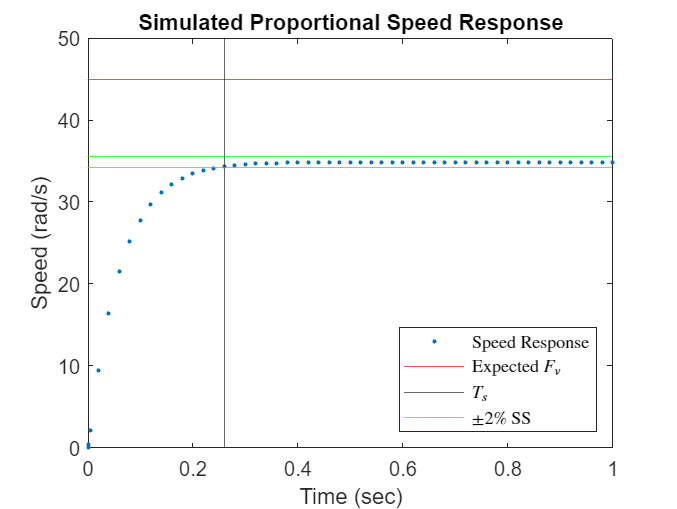

% plot speed response
plot(out.Y.Time, out.Y.Data, '.')
yline(r, 'r')
xline(t(1))
yline(F_v * 0.98, 'g')
ylim([0 50])
yline(F_v * 1.02, 'g')
title("Simulated Proportional Speed Response")
xlabel("Time (sec)")
ylabel("Speed (rad/s)")
legend({"Speed Response", "Expected $F_v$", '$T_s$', '$\pm{2\%}$ SS'},'Interpreter','latex', 'Location','southeast') 

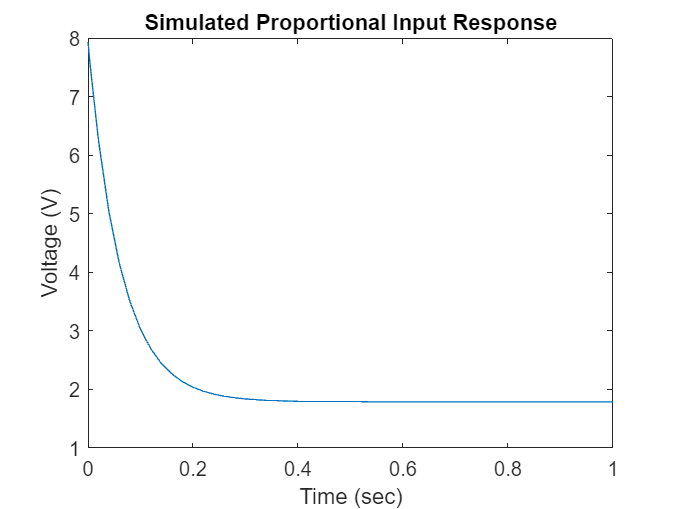


% plot input response
plot(out.u.Time, out.u.Data)
title("Simulated Proportional Input Response")
xlabel("Time (sec)")
ylabel("Voltage (V)")

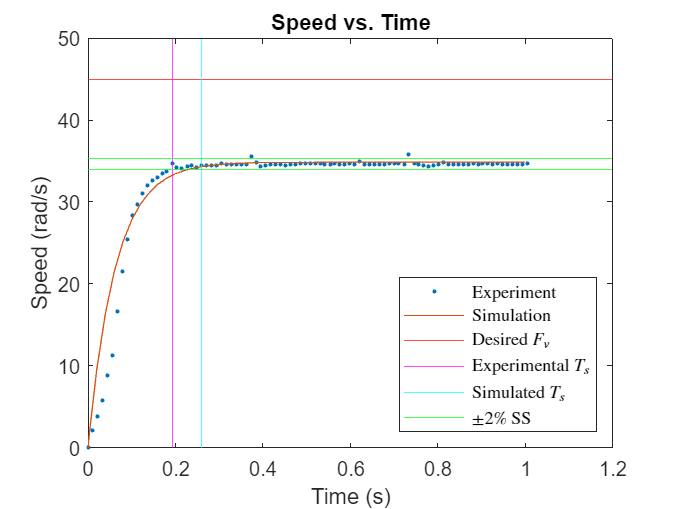

% plot speed
plot(time, speed, '.')
hold on 
plot(out.Y.Time, out.Y.Data)
hold off
yline(r, 'r')
xline(T_s_exp, 'm')
xline(T_s_sim, 'c')
yline(0.98 * Omega_ss, 'g')
yline(1.02 * Omega_ss, 'g')
ylim([0 50])
title("Speed vs. Time")
xlabel("Time (s)")
ylabel("Speed (rad/s)")
legend({'Experiment', 'Simulation', 'Desired $F_v$', 'Experimental $T_s$', 'Simulated $T_s$', '$\pm{2\%}$ SS'},'Interpreter','latex', 'Location','southeast') 

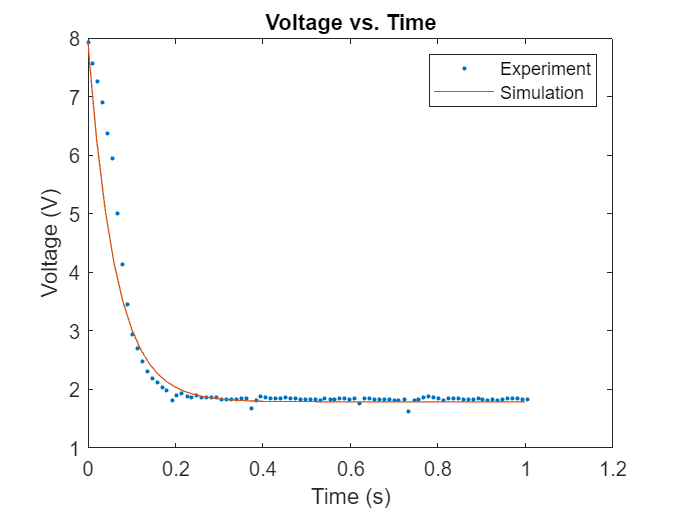


% plot input voltage
plot(time, input, '.')
hold on 
plot(out.u.Time, out.u.Data)
hold off
title("Voltage vs. Time")
xlabel("Time (s)")
ylabel("Voltage (V)")
legend('Experiment', 'Simulation')

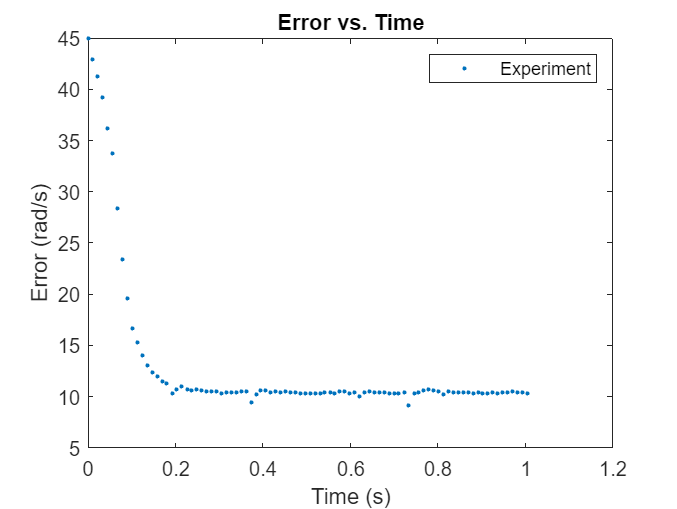


% plot error
plot(time, error, '.')
title("Error vs. Time")
xlabel("Time (s)")
ylabel("Error (rad/s)")
legend('Experiment')